# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.1 Stripmap SAR Range Resolution

## Calculate the range resolution in the slant plane

$\delta_{r\;} =\frac{c\;}{2B}\;\left(m\right)$   Equation (2.2)

% Clear the workspace
clear

% Waveform bandwidth (Hz)
waveform_bandwidth = linspace(1e6, 20e6, 1e3);

% Calculate the range resolution (m)
range_resolution = range_resolution_slant_plane(waveform_bandwidth);

### Plot the results

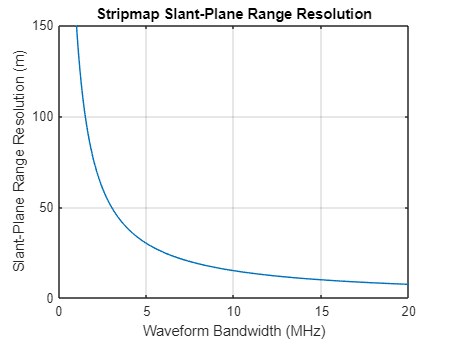

figure;
plot(waveform_bandwidth / 1e6, range_resolution);
xlabel('Waveform Bandwidth (MHz)')
ylabel('Slant-Plane Range Resolution (m)');
title('Stripmap Slant-Plane Range Resolution')
grid on

## Calculate the range resolution in the ground plane

$\delta_{g\;\;} =\frac{c\;}{2B\;\cos {\;\theta }_{i\;} }\;\left(m\right)$  Equation (2.3)

% Waveform bandwidth (Hz)
waveform_bandwidth = linspace(1e6, 20e6, 1000);

% Look angle (deg)
look_angle = [30, 40, 50, 60];

% Calculate the range resolution (m)
for i = 1:length(look_angle)
    range_resolution(i,:) = range_resolution_ground_plane(waveform_bandwidth, look_angle(i));
end


### Plot the results

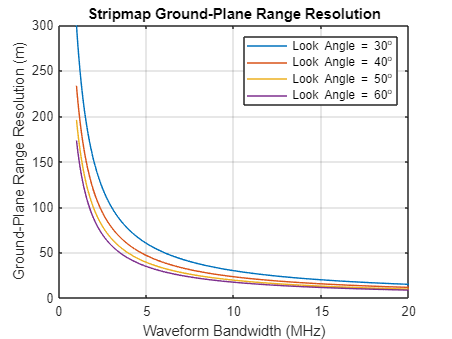

figure;
plot(waveform_bandwidth/1e6, range_resolution);
xlabel('Waveform Bandwidth (MHz)')
ylabel('Ground-Plane Range Resolution (m)');
title('Stripmap Ground-Plane Range Resolution')
legend('Look Angle = 30^o', 'Look Angle = 40^o', 'Look Angle = 50^o', 'Look Angle = 60^o')
grid on